# Práctica 8.

#### Ejercicio 1.

Se pide construir la geometría correspondiente a la figura. No hay más que abrir *pdetool* y a continuación `p8ej1.m`.

pdetool

#### Ejercicio 3.

Se pide trabajar con la ecuación de Poisson sobre el disco unidad.

a) $u(x,y)=\frac{1-x^{2}-y^{2}}{4}$ es solución fuerte del problema, pues$\nabla u=\left(-\frac{2x}{4},-\frac{2y}{4}\right)=-\left(\frac{x}{2},\frac{y}{2}\right)$ y $\nabla\cdot\nabla u=-\nabla \left(\frac{x}{2},\frac{y}{2}\right)=-\frac{1}{2}-\frac{1}{2}=-1$ y por tanto $-\Delta u=1$, como queríamos probar.

b) Introducimos el producto escalar con una función de prueba $v$ para transformar la ecuación de Poisson: $-\int_{\Omega}\Delta uvdx=\int_{\Omega}fvdx\iff-\int_{\Omega}\Delta uvdx=\int_{\Omega}vdx$ pues $f=1$; integrando por partes resulta $-\int_{\Omega}\Delta uvdx=\int_{\Omega}\nabla u\cdot\nabla vdx$ y por tanto la forma débil de la ecuación es $\int_{\Omega}\nabla u\cdot\nabla vdx=\int_{\Omega}vdx$ con $a(u,v)=\int_{\Omega}\nabla u\cdot\nabla vdx$ y $L(v)=\int_{\Omega}vdx$. Dado que $v$ es arbitraria, también $u(x,y)$ antes definida será solución del problema débil, por serlo del problema fuerte.

c) Tenemos por tanto $a(u,v)$ forma bilineal y continua sobre el círculo unidad y coerciva y tenemos que $L(v)$ es un operador lineal continuo sobre el dominio. Dado que la ecuación es $a(u,v)=L(v)$, basta aplicar Lax-Milgram para deducir que el problema admite una solución única $u(x,y)$ que será la que ya hemos encontrado.

d) Tenemos un resultado teórico para la cota de error de la solución si $u\in H^{2}(a,b)$ de la aproximación por elementos finitos de Lagrange lineales en dimensión 1D de $\|u^{(l)}-u^{(l)}_{h}\|_{L^{2}(a,b)}=O(h^{2-l}),\ l\in\{0,1\}$. Para su gradiente será $O(h^{1-l})$.

e) Utilizamos *pdetool*, abrimos ej3 y simplemente probamos distintos mallados.

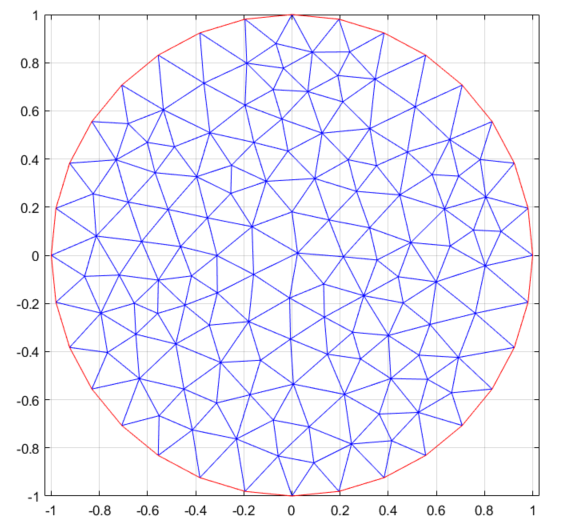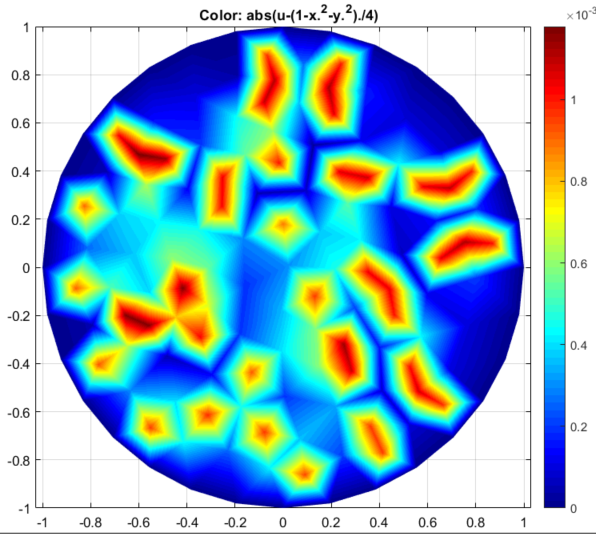

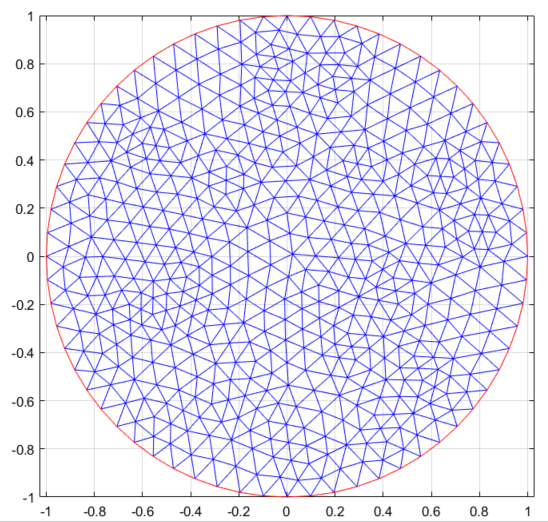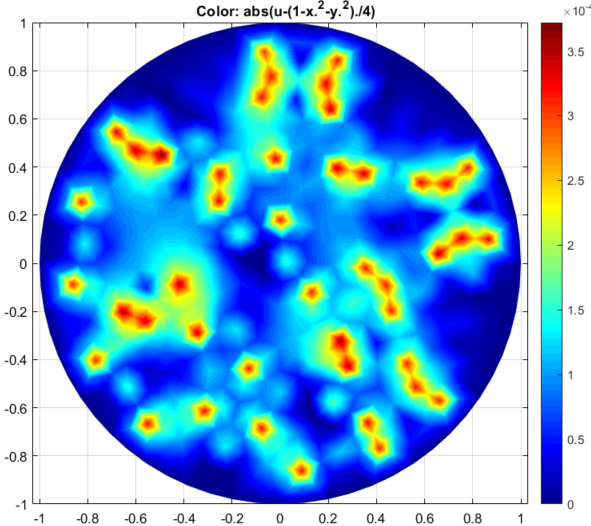

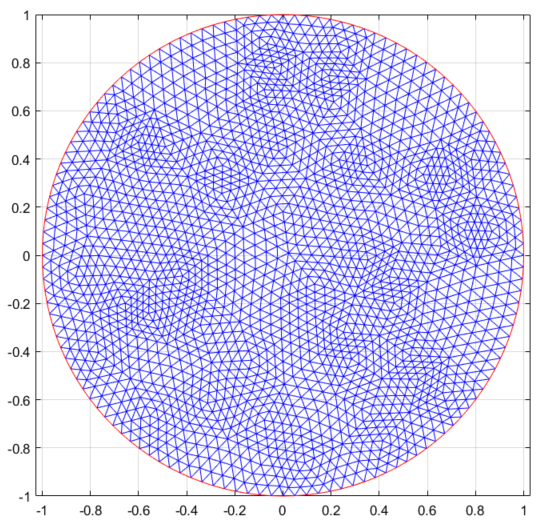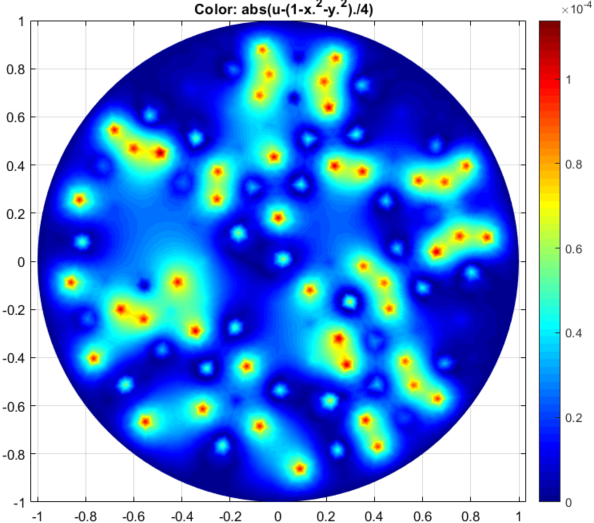

f) Exportamos la solución y la malla desde el propio *pdetool*. La función que mide el parámetro de refinamiento es `paraRef(t,p)`, indicada al final.

paraRef(t,p)

ans = 3.2233e-04

g) Cálculo de la norma de una función en $L^{2}(\Omega)$, $\|v_{h}\|_{L^{2}(\Omega)}$ y cálculo del error de la aproximación. Función `normal2` en el Anexo.

error_u=u-(1-p(1,:)'.^2-p(2,:)'.^2)/4;
normal2(error_u,t,p,1,1)

ans = 1.3838e-05

h) Cálculo del gradiente $\|\nabla v_{h}\|_{L^{2}(\Omega)}$ y cálculo del error de la aproximación.

% Cálculo del gradiente de la solución asociada a la malla considerada
normal2(u,t,p,2,2)

ans = 0.0769

i) Cálculo de la norma de una función en $L^{2}(\Omega)$, $\|v_{h}\|_{H^{1}(\Omega)}$ y cálculo del error de la aproximación con esta norma.

z=sqrt(normal2(error_u,t,p,1,1)^2+normal2(u,t,p,2,2)^2)

z = 0.0769

#### Ejercicio 5.

Se pide resolver la ecuación del calor para el dominio y las condiciones de contorno indicadas.

a) Exportar la malla y la solución a la ventana de comandos. Identificar el valor de la solución aproximada en un nodo particular y para un cierto instante.

u(28,25)

ans = 85.6425

punto=[p(1,28),p(2,28)]

punto =     0.0500    0.2000


tiempo=0:0.1:5;
tiempo(28)

ans = 2.7000

b) Vamos a definir un test académico asociado a la misma geometría, el mismo intervalo de tiempo, y al tipo de condiciones de contorno dadas en cada frontera. Proponemos la solución $u(x,y,t)=te^{x+y}$; es claro que verifica la ecuación de conducción del calor con $f(x,y,t)=(1-2t)e^{x+y}$. No tenemos más que ver ahora las condiciones de contorno: queremos que haya una condición Dirichlet en $x=-0.5$: ahí nuestra función vale $u(-0.5,y,t)=te^{y-0.5}$; en el resto de fronteras tenemos condiciones Neumann: como se trata de una figura rectangular, $\frac{\partial u}{\partial n}$ valdrá $\frac{\partial u }{\partial x}=u$ o bien $\frac{\partial u }{\partial y}=u$. Introduciendo esto en el *pdetool*, arroja el siguiente gráfico para el instante final:

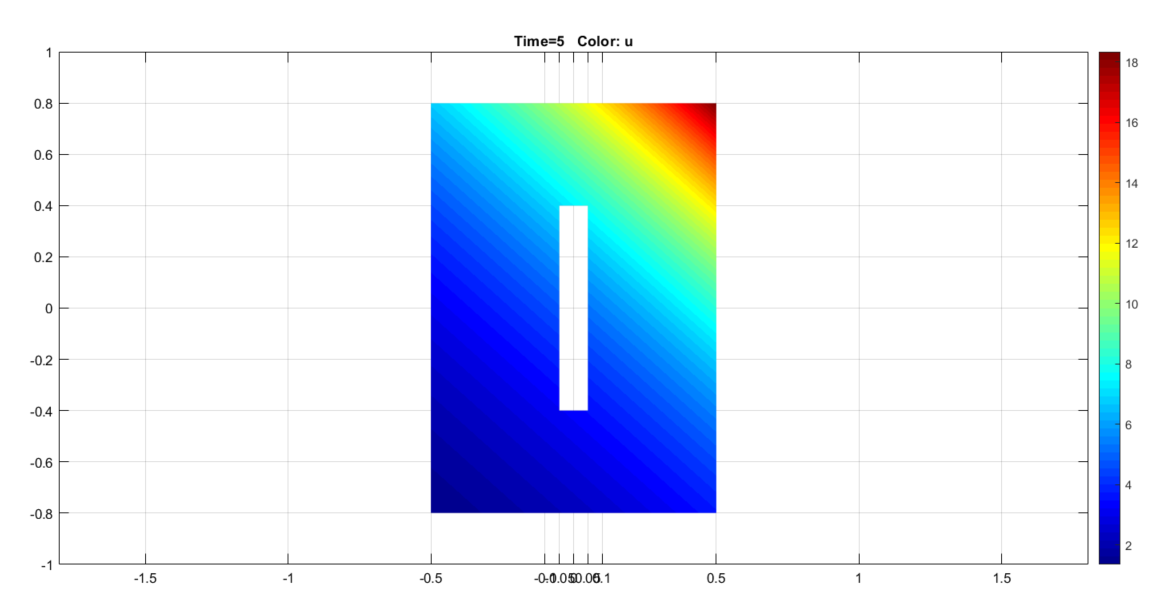

Procedemos a repetir el análisis del apartado anterior sobre este ejemplo.

u(28,25)

ans = 3.0816

punto=[p(1,28),p(2,28)]

punto =     0.0500    0.2000


tiempo=0:0.1:5;
j=28;
tiempo(j)

ans = 2.7000

c) Utilizar la función programada en el ejercicio anterior para calcular lo siguiente.

% Parámetro de la malla:
paraRef(t,p)

ans = 1.1610e-05

% Error solución L2
v=u(:,j);
error_u=v-(1-p(1,:)'.^2-p(2,:)'.^2)/4;
normal2(error_u,t,p,1,1)

ans = 4.2601

% Error gradiente L2
normal2(v,t,p,2,2)

ans = 1.7640e+03

d) Programar una función que permita calcular lo siguiente.  Analizar la dependencia de sus valores con el grado de refinamiento de la malla.

for j=1:tiempo(end)
    v=u(:,j);
    error_u=v-(1-p(1,:)'.^2-p(2,:)'.^2)/4;
    normaSolVec(j)=normal2(error_u,t,p,1,1);
    normaGradVec(j)=normal2(v,t,p,2,2);
end

normaSol=max(normaSolVec)

normaSol = 0.4941

normaGrad=max(normaGradVec)

normaGrad = 318.0966

## Anexo.

function z=paraRef(t,p)
% Función que calcula el parámetro de refinamiento de la malla como el máximo
% de las áreas de los elementos
% El cálculo se realiza sobre la malla t en el formato de pdetool
% El argumento p representa las coordenadas de los nodos

nel=length(t(1,:));
areak=ones(1,nel);
for k=1:nel
    Bk=[p(:,t(2,k))-p(:,t(1,k)), p(:,t(3,k))-p(:,t(1,k))];
    areak(k)=abs(det(Bk))*0.5;
end

z=norm(areak, Inf);
end

function z=normal2(u,t,p,opint,metodo)
% Función que calcula la norma L^2 de una función u definida en cada nodo
% de la malla sobre el dominio definido por la malla t en el formato de
% pdetool.
% La función u debe estar definida sobre los nodos de la malla.
% La matriz p representa las coordenadas de los nodos.
% La matriz t representa la información sobre los elementos: sus vértices y
% el dominio al que pertenecen.
% opint es la opción de integración.
% opint==1, si se utiliza la aproximación numérica del valor medio
% opint==2, si se calcula la integral exacta sobre cada elemento
% Si el número de argumentos es 3, se entiende que opint=1
% Metodo indica si calcula con la solución o con el gradiente.

if metodo==1;
    if nargin==3
        opint=1;
    end
    if opint==2
        syms x y
        PRef=[1-x-y, x, y];
        integrando=PRef'*PRef;
        Integ1=int(integrando, 'y', 0, 1-x);
        Integ2=int(Integ1,'x',0,1);
        IntegralRef=eval(Integ2);
    end
    nel=length(t(1,:));
    z=0;
    for k=1:nel
        uk=u(t(1:3,k));
        Bk=[p(:,t(2,k))-p(:,t(1,k)), p(:,t(3,k))-p(:,t(1,k))];
        if opint==1
            areak=abs(det(Bk))*0.5;
            Integralk=sum(uk.^2)/3*areak;
        else
            Integralk=abs(det(Bk))*uk'*IntegralRef*uk;
        end
        z=z+Integralk;
    end
    z=sqrt(z);

else
    [ux,uy]=pdegrad(p,t,u);
    nel=size(t,2);
    bar_e=[];
    for k=1:nel
        bar_e=[bar_e, 1/3.*[sum(p(1,t(1:3,k))), sum(p(2,t(1:3,k)))]'];
    end
    z=max(norm(ux+bar_e(1,:)/2,2), norm(uy+bar_e(2,:)/2,2));
end

end